# EE 451 Digital Signal Processing

# Lisa Jacklin

# Final Review 

## In Class Problem 1

%xa is bandlimited to 1khz. interest range is 250 to 500hz.
% the signal is sampled with double the minimum sampling frequency, giving
% xn
%must be decimated digitaily by 4 

%variables and important pieces
D = 4;
bandlimited = 1000; 

f = [250 500]; %this is the range we are interested in. 
%this is a bandpass! this is how we need to find this! 
%we know that this is a bandpass because we are given a particular range of
%values that we are looking at.

Fs = 4000; %we know that Fs must be 2*Fsmin.

%since we know that this is the bandpass, we need to find the length and
%the cuttoff frequency

M = length(f); %check me!
%this needs to be displayed with a hamming window now that we have the
%length
window = hamming(M); % using a hamming  window we can check to the length of the window and from here, determine the resulting cutoffs!
%from this window we should be able to obtain two cutoff frequencies, wc1
%and wc2 which we will be using.
%note that for Hamming: delta w = 8*pi/M

%note that As, Rp, are both items which since not given, we are guessing
%and using to get values required.
As = 80;
Rp = 0.01;
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
ds = [d1 d2];
a = [ 0 1];

%so what is wc, wp? what is the range? delta w?

%we also need to include the decimation here?


%sketch the ideal filter Hw that will be applied to the signal if we are
%only looking at the frequencies of interest.

%as we have learned we will need to build an idea_lp filter
%we need to find the length of the signal requested as well as the cutoff
%frequency to find the ideal here.

%I still need the frequency cutoff
%Hw = ideal_lp(, M);



%design a FIR filter



## In Class Problem -- Solution and Notes

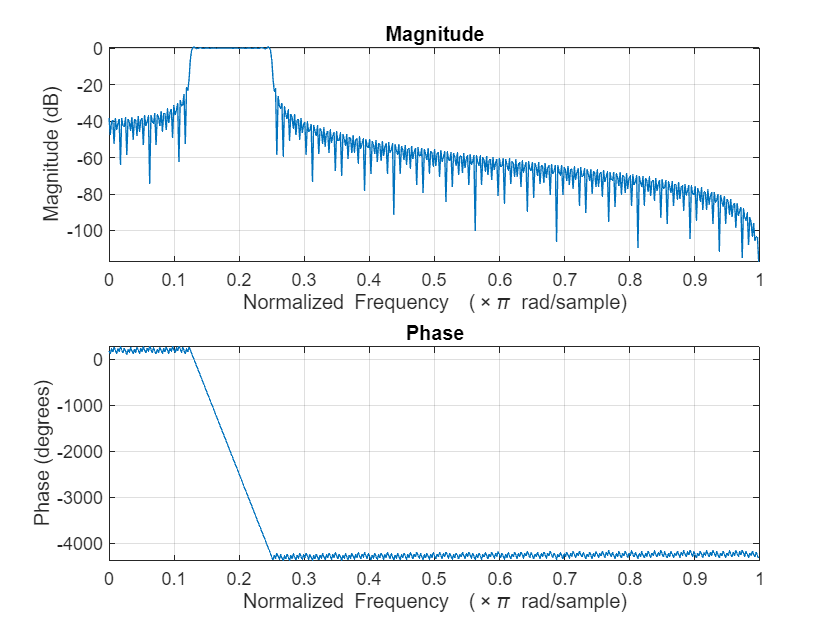

%we know that we have a bandlimited frequency of 1000, and to fit niquist,
%we need 2000hz, thus Fs = 4000 which is 2 times the lowest sampling.

%consider the decimation, we need to take this into consideration as we
%want to shrink things by 1/4 to be able to decimate to a range from 0 to
%pi without aliasing out of the desired window.

%since we have a freuqency range of 250 and 500 which correspond to pi/8
%and pi/4, we can build a bandpass

%if we are given the frequency resolution, we can calculate the delta w.
%consider if we have a delta f of 4000, and the frequency sampling, we can
%find M. 
% M = Fs/deltaf
M = 400; %note that this is the starting value for M, which needs to be adjusted.
wc1 = pi/4;
wc2 = pi/8;

%once these cutoffs are found, we can find the range in which we need to
%work for the ideal filter.
hn = ideal_lp(wc1, M) - ideal_lp(wc2, M);

freqz(hn); %what does the domain look like? Is this what you expect?

%FINISH MEEEEE


## In Class Problem 2 - IIR Filter Design

%2 high pass IIR filters (one with impulse invariance, one using bilinear)

%note that we don't have a sampling frequency, So i'm going to make one
%note that when you don't have a sampling frequency, you can plug ina value
%(the best value is one!)
Fs = 1; Ts = 1/Fs;
wc = 0.7*pi/Fs; %this should give us radians for the passband
wp = 0.8*pi/Fs; %note that the transition bandwith is used here
transition_bw = 0.1*pi;

unity = pi; %this is the filter gain we want to achieve
stopband_att = 50; %attentation of 50 in the sb

%we are not given a ripple in the passband, so I am assigning one
Rp = 0.1;

%first, we need to find the omega values that work with the analog to
%digital cnversion

OmegaP = (2/Ts)*tan(wc/2);
OmegaS = (2/Ts)*tan(wp/2);

%now that we have these values, we can build in the butterworth design
%note that this is creating a lowpass value
[num, den] = afd_butt(OmegaP, OmegaS, Rp, stopband_att );


*** Butterworth Filter Order = 17 


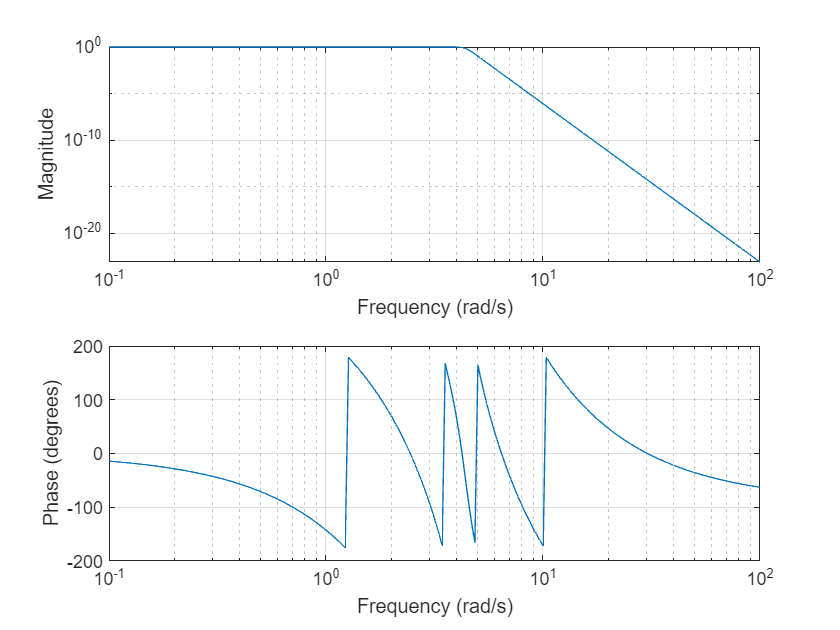

freqs(num, den); %to help me check!

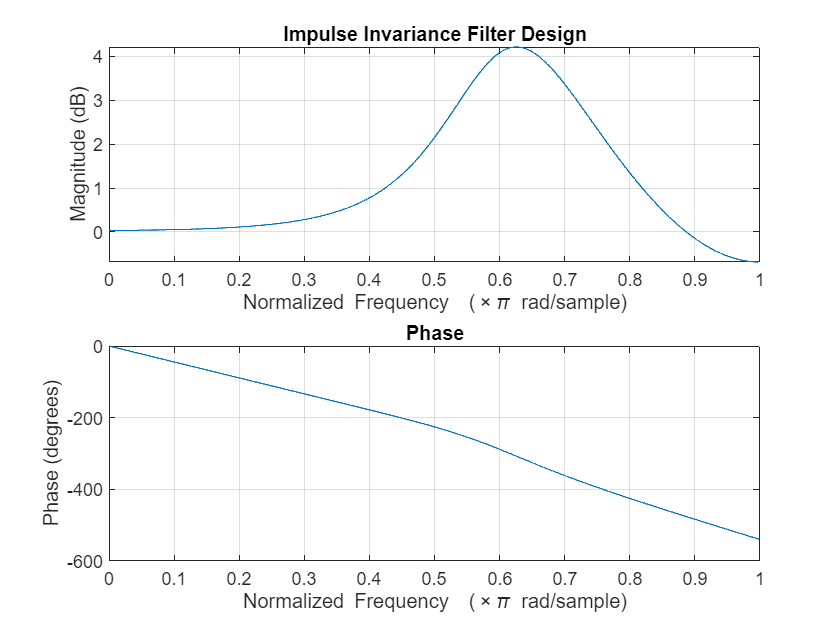

%now that I have this, I can begin to plot the impulse invariance, and the
%bilinear

%impulse invariant
[b, a] = imp_invr(num, den, Ts); %note that all of these are given above!
binv = b; ainv = a;
freqz(b,a);
title("Impulse Invariance Filter Design")

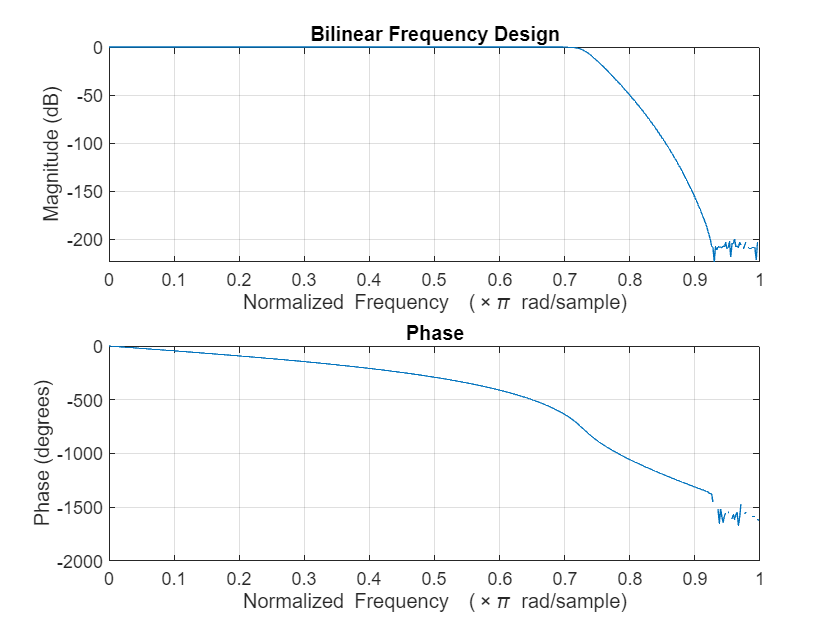

%Bilinear usage
[b2, a2] = bilinear(num, den, Fs); %all these are given once again up above!
bbi = b; abi = a;
freqz(b2, a2);
title("Bilinear Frequency Design");


%now, to use zmapping? is it required at all?


Arrays have incompatible sizes for this operation.

Error in EE451_FinalReview>zmapping (line 236)
    bz = bz+bZ(k+1)*conv(pln,pld);

Related documentation

## In Class Problem 2 - Solution and Notes

## Functions Required

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end

function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end
function [b,a] = imp_invr(c,d,T)
% Impulse Invariance Transformation from Analog to Digital Filter
% ---------------------------------------------------------------
% [b,a] = imp_invr(c,d,T)
%  b = Numerator polynomial in z^(-1) of the digital filter
%  a = Denominator polynomial in z^(-1) of the digital filter
%  c = Numerator polynomial in s of the analog filter
%  d = Denominator polynomial in s of the analog filter
%  T = Sampling (transformation) parameter
%
[R,p,k] = residue(c,d);  p = exp(p*T);
[b,a] = residuez(R,p,k);  b = real(b'); a = real(a');
end

function [b,a] = afd_butt(Wp,Ws,Rp,As)
% Analog Lowpass Filter Design: Butterworth
% -----------------------------------------
% [b,a] = afd_butt(Wp,Ws,Rp,As);
%  b = Numerator coefficients of Ha(s)
%  a = Denominator coefficients of Ha(s)
% Wp = Passband edge frequency in rad/sec; Wp > 0
% Ws = Stopband edge frequency in rad/sec; Ws > Wp > 0
% Rp = Passband ripple in +dB; (Rp > 0)
% As = Stopband attenuation in +dB; (As > 0)
%
if Wp <= 0
        error('Passband edge must be larger than 0')
end
if Ws <= Wp
        error('Stopband edge must be larger than Passband edge')
end
if (Rp <= 0) | (As < 0)
        error('PB ripple and/or SB attenuation ust be larger than 0')
end
N = ceil((log10((10^(Rp/10)-1)/(10^(As/10)-1)))/(2*log10(Wp/Ws)));
fprintf('\n*** Butterworth Filter Order = %2.0f \n',N)
OmegaC = Wp/((10^(Rp/10)-1)^(1/(2*N)));
[b,a]=u_buttap(N,OmegaC);
end

function [b,a] = u_buttap(N,Omegac)
% Unnormalized Butterworth Analog Lowpass Filter Prototype
% --------------------------------------------------------
% [b,a] = u_buttap(N,Omegac);
%      b = numerator polynomial coefficients of Ha(s)
%      a = denominator polynomial coefficients of Ha(s)
%      N = Order of the Butterworth Filter
% Omegac = Cutoff frequency in radians/sec
%
[z,p,k] = buttap(N);
      p = p*Omegac;
      k = k*Omegac^N;
      B = real(poly(z));
      b0 = k;  b = k*B;  a = real(poly(p));
end

function [bz,az] = zmapping(bZ,aZ,Nz,Dz)
% Frequency band Transformation from Z-domain to z-domain
% -------------------------------------------------------
% [bz,az] = zmapping(bZ,aZ,Nz,Dz)
% performs:
%           b(z)  b(Z)|
%          ---- = ----|     N(z)
%          a(z)   a(Z)|@Z = ----
%                           D(z)

bNzord = (length(bZ)-1)*(length(Nz)-1);
aDzord = (length(aZ)-1)*(length(Dz)-1);
bzord = length(bZ)-1; azord = length(aZ)-1;
bz = zeros(1,bNzord+1);
for k = 0:bzord
    pln = [1];
    for l = 0:k-1
        pln = conv(pln,Nz);
    end
    pld = [1];

    for l = 0:bzord-k-1
        pld = conv(pld,Dz);
    end
    bz = bz+bZ(k+1)*conv(pln,pld);
end
az = zeros(1,aDzord+1);
for k = 0:azord
    pln = [1];
    for l = 0:k-1
        pln = conv(pln,Nz);
    end
    pld = [1];
    for l = 0:azord-k-1
        pld = conv(pld,Dz);
    end
    az = az+aZ(k+1)*conv(pln,pld);
end
end